# FIR for ECG Denoising

12 bits

Sampling Frequency 128 Hz

data = readmatrix('18177_normal_sinus_rhythm.txt');
x_axis = (1:1280)/128;

**ECG1**

ECG1 = data(:,2);

tiles1 = tiledlayout(4, 1);
nexttile
plot(x_axis, ECG1);
xlabel("t (seconds)")
ylabel("voltage (mV)")
title("ECG1")

**FFT: ECG1**

Fs = 128;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1280;             % Length of signal
t = (0:L-1)*T;        % Time vector

ft_ECG1 = fft(ECG1);
P2 = abs(ft_ECG1/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f_ecg1 = Fs*(0:(L/2))/L;
nexttile
plot(f_ecg1,P1) 
title("Amplitude Spectrum of ECG1")
xlabel("f (Hz)")
ylabel("|P1(f)|")

**Low pass filter to eliminate base-line: ECG1**

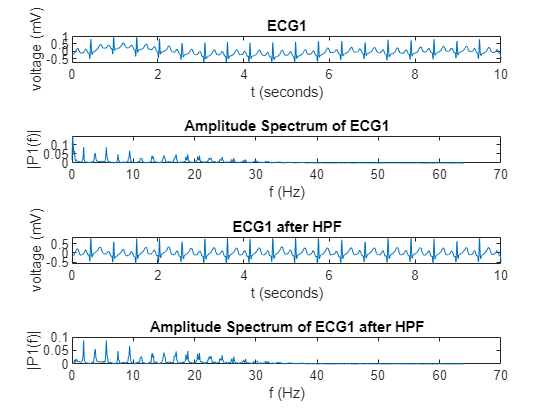

fil = filter(Hhp, ECG1);
ft_fil = fft(fil);
nexttile
plot(x_axis, fil);
xlabel("t (seconds)");
ylabel("voltage (mV)");
title("ECG1 after HPF");
P2 = abs(ft_fil/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f_hpf = Fs*(0:(L/2))/L;
nexttile
plot(f_hpf,P1);
title("Amplitude Spectrum of ECG1 after HPF");
xlabel("f (Hz)");
ylabel("|P1(f)|");


% SNR
r = snr(ECG1, fil);
fprintf("SNR: %.4f", r)

SNR: 1.7630

**DWT**

cA: approximation coefficients

cD: detail coefficients

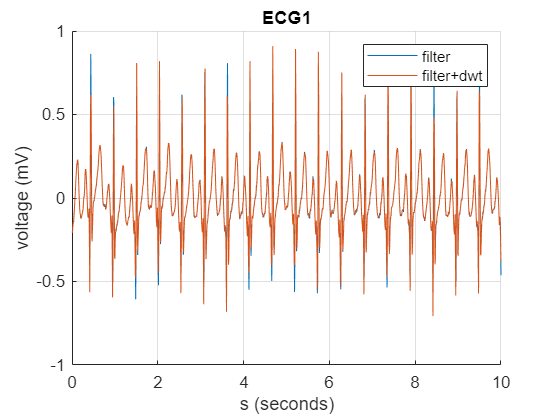

[cA, cD] = dwt(fil, 'sym4', 'zpd');
xrec = idwt(cA, zeros(size(cA)), 'sym4');
figure; hold on; grid on;
plot(x_axis, fil)
plot(x_axis, xrec)
title('ECG1')
xlabel("s (seconds)")
ylabel("voltage (mV)")
legend('filter', 'filter+dwt')

snr(ECG1, xrec) - snr(ECG1, fil)

ans = 0.1626

**Power-line interface noise**

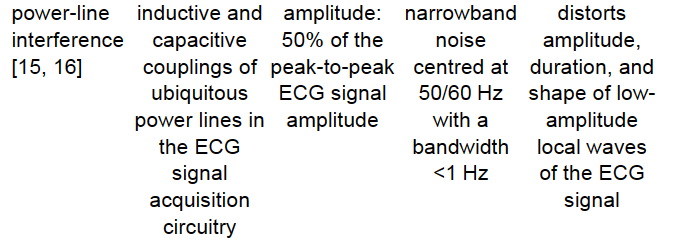

**Muscle-artefacts noise**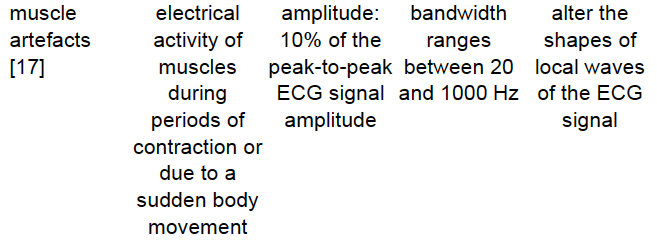

**ECG2**

ECG2 = data(:,3);
tiles2 = tiledlayout(4, 1);
nexttile
plot(x_axis, ECG2);
ylabel("voltage (mV)");
xlabel("t (seconds)")
title("ECG2")


**FFT: ECG2**

Fs = 128;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1280;             % Length of signal
t = (0:L-1)*T;        % Time vector

ft_ECG2 = fft(ECG2);
P2 = abs(ft_ECG2/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
nexttile
plot(f,P1) 
title("Amplitude Spectrum of ECG2")
xlabel("f (Hz)")
ylabel("|P1(f)|")

**Low pass filter to eliminate base-line: ECG2**

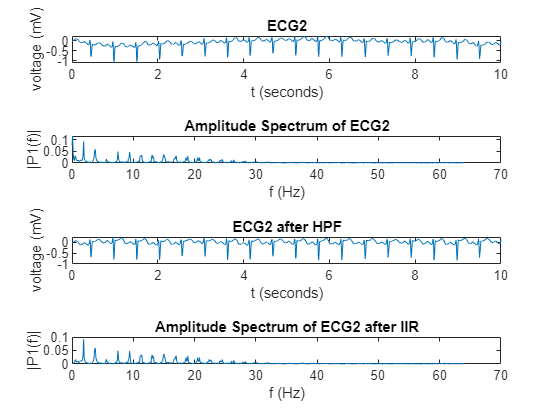

fil = filter(Hhp, ECG2);
ft_fil = fft(fil);
nexttile
plot(x_axis, fil);
ylabel("voltage (mV)");
xlabel("t (seconds)");
title("ECG2 after HPF");
P2 = abs(ft_fil/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f_hpf = Fs*(0:(L/2))/L;
nexttile
plot(f_hpf,P1);
title("Amplitude Spectrum of ECG2 after IIR");
xlabel("f (Hz)");
ylabel("|P1(f)|");

r = snr(ECG2, fil)

r = 2.0066

**DWT**

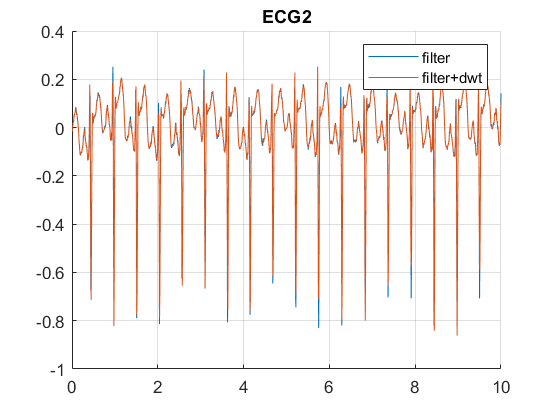

[cA, cD] = dwt(fil, 'sym4', 'zpd');
xrec = idwt(cA, zeros(size(cA)), 'sym4');
figure; hold on; grid on;
plot(x_axis, fil)
plot(x_axis, xrec)
title('ECG2')
legend('filter', 'filter+dwt')

snr(ECG1, xrec) - snr(ECG1, fil)

ans = 0.1064